**Data**

x = [1 2 3 4 5]'

x =      1
     2
     3
     4
     5


y = [2.2 2.8 3.6 4.5 5.5]'

y =     2.2000
    2.8000
    3.6000
    4.5000
    5.5000


**Plot data**

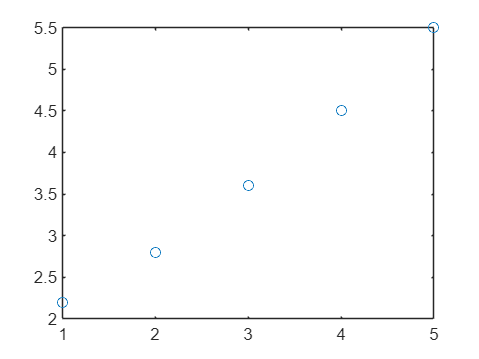

plot(x,y,'o')

**Create Z matrix**

z = [ones(size(x)) x 1./x]

z =     1.0000    1.0000    1.0000
    1.0000    2.0000    0.5000
    1.0000    3.0000    0.3333
    1.0000    4.0000    0.2500
    1.0000    5.0000    0.2000


**Solve for unknown parameters  a  **

a = (z'*z) \ (z'*y)

a =     0.3745
    0.9864
    0.8456


**Plot data and the best fitted curve**

yy = z*a

yy =     2.2066
    2.7702
    3.6157
    4.5317
    5.4758


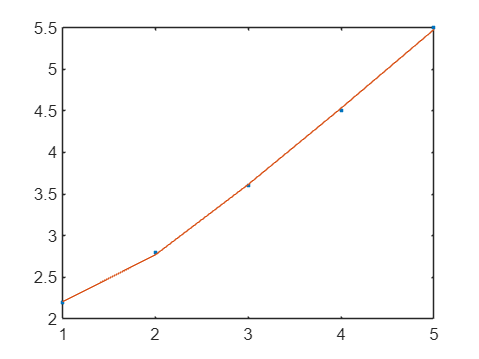

plot(x, y, '.', x, yy, '-')

**Compute  Sr  (the sum of the squares of the residuals between the best-fit curve and the data)**

Sr = sum((y-z*a).^2)

Sr = 0.0028

**Compute  St   (the sum of the squares of the residuals between the data points and the mean)**

St = sum((y-mean(y)).^2)

St = 6.9480

**Compute  r2  (the coefficient of determination)**

r2 = 1 - Sr/St

r2 = 0.9996

**Compute  syx  (the standard error of the estimate)  **

syx = sqrt(Sr/(length(x)-length(a)))

syx = 0.0372

**Predict the value of y for the given x**

xp = 2.5

xp = 2.5000

yp = a(1) + a(2)*xp + a(3)/xp

yp = 3.1789